# EXP.4. Sensor Data Acquisition

Open port to Pico

clear s % closes ports already open
s = serialport('COM4',9600) % Check COM#

s =   Serialport with properties:

                 Port: "COM4"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


configureTerminator(s,'CR') % end lines with \r

Prompt the user for sample rate and number of samples and send to the Pico.

sample_rate = input("Please enter the sample rate: ") % prompt user for sample rate

sample_rate = 2

N = input("Please enter the number of samples: ") % prompt user for number of samples

N = 60

s.writeline(string(sample_rate)) % write sample rate to Pico
s.writeline(string(N)) % write number of samples to Pico

Receive results and store them in two arrays sensor1 and sensor2.

sensor1 = zeros(1,N); % initialize sensor1 array
sensor2 = zeros(1,N); % initialize sensor2 array
for k = 1:N % loop through all samples
    sensor1(1,k) = s.readline(); % read value from Pico and update sensor1 array
    sensor2(1,k) = s.readline(); % read value from Pico and update sensor2 array
end
sensor1

sensor1 =        61438       61519       61455       61422       61471       61438       61455       61438       61471       61471       61374       61455       61503       61727       61503       61471       61422       61471       61471       61471       61342       61118       60750       60686       60510       60318       60238       60222       60190       60110       60126       60062       60062       59998       60014       60094       59998       59966       59950       59918       59662       59486       59326       59198       59278       59310       59502       59358       59182       59326


sensor2

sensor2 =        61278       61262       61278       61294       61406       61326       61262       61182       61278       61262       61230       61246       61214       61246       61294       61294       61214       61342       61471       61599       61711       61887       62015       62175       62303       62399       62655       62623       62767       62879       62991       63199       63279       63391       63391       63471       63503       63471       63599       63823       63711       63903       63951       64143       64191       64191       64079       64175       63903       63935


Convert sensor1 and sensor2 to degrees Fahrenheit and store in temp1 and temp2.

temp1 = convert_to_temp(sensor1) % convert sensor1 ADC values to temperature

temp1 =    97.1954   97.9295   97.3495   97.0503   97.4945   97.1954   97.3495   97.1954   97.4945   97.4945   96.6153   97.3495   97.7845   99.8148   97.7845   97.4945   97.0503   97.4945   97.4945   97.4945   96.3252   94.2949   90.9594   90.3793   88.7841   87.0438   86.3187   86.1737   85.8837   85.1586   85.3036   84.7235   84.7235   84.1434   84.2884   85.0135   84.1434   83.8534   83.7083   83.4183   81.0980   79.5027   78.0525   76.8923   77.6174   77.9075   79.6477   78.3425   76.7473   78.0525


temp2 = convert_to_temp(sensor2) % convert sensor2 ADC values to temperature

temp2 =    95.7452   95.6001   95.7452   95.8902   96.9053   96.1802   95.6001   94.8750   95.7452   95.6001   95.3101   95.4551   95.1651   95.4551   95.8902   95.8902   95.1651   96.3252   97.4945   98.6547   99.6698  101.2650  102.4252  103.8754  105.0356  105.9057  108.2261  107.9360  109.2412  110.2564  111.2715  113.1568  113.8819  114.8971  114.8971  115.6222  115.9122  115.6222  116.7824  118.8127  117.7975  119.5378  119.9728  121.7131  122.1482  122.1482  121.1330  122.0032  119.5378  119.8278


save 'sensor_data.mat' sensor1 sensor2 % save sensor data

Create a time series using linspace based on the number of samples and sample rate. All

three arrays should have the same number of elements.

time = linspace(0,N/sample_rate,N) % create x axis --> time (s)

time =          0    0.5085    1.0169    1.5254    2.0339    2.5424    3.0508    3.5593    4.0678    4.5763    5.0847    5.5932    6.1017    6.6102    7.1186    7.6271    8.1356    8.6441    9.1525    9.6610   10.1695   10.6780   11.1864   11.6949   12.2034   12.7119   13.2203   13.7288   14.2373   14.7458   15.2542   15.7627   16.2712   16.7797   17.2881   17.7966   18.3051   18.8136   19.3220   19.8305   20.3390   20.8475   21.3559   21.8644   22.3729   22.8814   23.3898   23.8983   24.4068   24.9153


Plot both temperatures vs. time. Make sure to include axis labels, legend, and title.

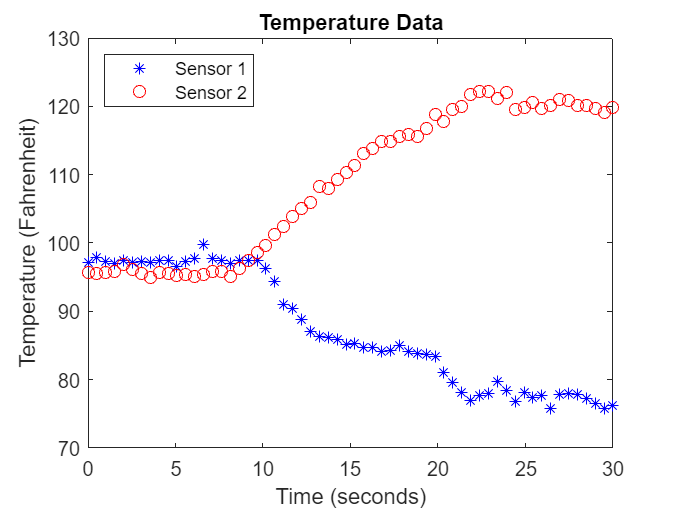

plot(time,temp1,'b*') % plot temp1 data
hold on
plot(time,temp2,'ro') % plot temp2 data
hold off
title("Temperature Data")
legend(["Sensor 1", "Sensor 2"], 'Location', 'northwest')
xlabel("Time (seconds)")
ylabel("Temperature (Fahrenheit)")

function temp = convert_to_temp(n) % convertes ADC value into temperature in Fahrenheit

    temp = (((1/0.01)*((3.3/65535).*n) - 273.15)*(9/5)) + 32;

end